# # TODO 

# -add text; 

# -finish brain area section; 

# -change data format to tabular (csv)

# Spike Time Analysis

## Download and extract data

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo("https://uni-bonn.sciebo.de/s/3XSEhFukhfuGIK5", 'data/steinmetz_2017-01-08_Muller_spikes.csv')

Done!

download_from_sciebo("https://uni-bonn.sciebo.de/s/50LRzljOo96xwXQ", 'data/steinmetz_2017-01-08_Muller_events.csv')

Done!

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

spike_id = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_id");
spike_time = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_time");
spike_cell = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_cell");
spike_trial = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_trial");


data = table(spike_id, spike_time, spike_cell, spike_trial)

data = 1836009×4 table
    spike_id    spike_time    spike_cell    spike_trial
    ________    __________    __________    ___________

        1         2.3629          1              1     
        2         2.3849          1              1     
        3         1.4507          1              2     
        4         1.4596          1              2     
        5         1.9635          1              2     
        6         1.9653          1              2     
        7         1.9708          1              2     
        8         1.9727          1              2     
        9         1.9751          1              2     
       10         1.9776          1              2     
       11         1.5432          1              6     
       12         1.5456          1              6     
       13         1.5476          1              6     


writetable(data, "data/steinmetz_2017-01-08_Muller_spikes.csv")

**Example Exercise**

How many cells spiked during trial 1?

spike_cells_selected_trial = data(data.spike_trial==1,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 860

**Exercises**

How many cells spiked during trial 24?

spike_cells_selected_trial = data(data.spike_trial==24,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 830

How many cells spiked during the last trial?

last_trial = data.spike_trial(height(data))

last_trial = uint32
252

spike_cells_selected_trial = data(data.spike_trial==last_trial,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 919

Make a list of the number of spiking cells of each trial. **Hint** - use  `groupsummary(data, "coulum_A", "numunique", "coulmn_B")`

Name the result `n_spiking_cells`

n_spiking_cells = groupsummary(data, "spike_trial","numunique", "spike_cell").numunique_spike_cell

n_spiking_cells =    860
   839
   809
   879
   836
   848
   824
   853
   796
   804


What was the maximum number of spiking cells?

max(n_spiking_cells)

ans = 1001

Let's visualize the distribution of the number of spiking cells with a histogram.

hist(n_spiking_cells)
xlabel('number of spiking cells in a trial')
ylabel('frequency')

What is the minimum number of spiking cells? Compare this value to the histogram above

min(n_spiking_cells)

ans = 758

## Visualize the spiking activity using spike times

**Example Exercise**

Create a scatter plot to visualize spikes for a single neuron across multiple trials.

dd = data(data.spike_cell==12,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

**Exercises**

Create a scatter plot to visualize spikes for a neuron number 11 across multiple trials.

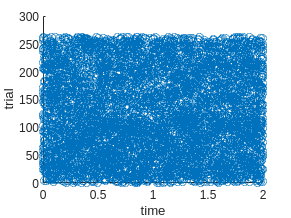

dd = data(data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Wow, that plot looks crowded! Instead of a circle,  plot with `|`. Use `help scatter` to find out out how

dd = data(data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial, "|")
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for all neurons in trial 83.

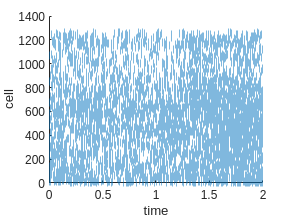

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')

help scatter

  scatter Scatter plot.
     scatter(X,Y) creates a scatter plot with markers at the locations
     specified by X and Y. One scatter object is created when X and Y are
     vectors. Multiple scatter plots are created if X or Y are matrices.
 
     scatter(X,Y,SZ) specifies the area of each marker in points squared.
     To plot all markers with the same size, specify SZ as a scalar. To
     plot each marker with a different size, specify SZ as a vector or
     matrix. If SZ is an empty vector, the default size is used.
 
     scatter(X,Y,SZ,C) specifies the marker colors. To plot all markers
     with the same color, specify C as a color name or an RGB triplet. To
     specify different colors for each scatter plot, specify C as an 
     m-by-3 matrix of RGB triplets with one color per scatter object. To
     specify different colors for each scatter point when a single scatter
     plot is created, specify C as an m-

We can vary the color of the points based of the spike time with the 4th argument of `scatter. `**Hint - **the 3rd argument will have to be empty - `[]`

Remake the above plot setting the color of the points to the spike time.

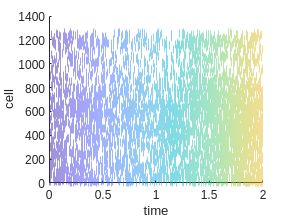

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, [], dd.spike_time,"|")
xlabel('time')
ylabel('cell')

Remake the plot above, giving the plot an appropriate title

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, [], dd.spike_time,"|")
xlabel('time')
ylabel('cell')
title('trial number 83')

## Relating spike timing to event-based variables

spike_trial = ncread("data/steinmetz_2017-01-08_Muller.nc","trial");
gocue = ncread("data/steinmetz_2017-01-08_Muller.nc","gocue");
response_time = ncread("data/steinmetz_2017-01-08_Muller.nc","response_time");
feedback_time = ncread("data/steinmetz_2017-01-08_Muller.nc","feedback_time");
active_trials = ncread("data/steinmetz_2017-01-08_Muller.nc","active_trials");

data_events = table(spike_trial, gocue, response_time, feedback_time,active_trials)

data_events = 261×5 table
    spike_trial     gocue     response_time    feedback_time    active_trials
    ___________    _______    _____________    _____________    _____________

         1         0.98282        1.2333           1.2716             1      
         2         0.90201        1.0666           1.1036             1      
         3          1.1136        1.3666           1.4024             1      
         4         0.68881        1.0168           1.0528             1      
         5          1.0176        1.1834           1.1936             1      
         6         0.61881       0.75082          0.78601             1      
         7          1.0288        1.1841             1.22             1      
         8          1.0124        1.1505            1.186             1      
         9           1.


data_events = data_events(data_events.active_trials==1,:);
writetable(data_events,"data/steinmetz_2017-01-08_Muller_events_active.csv")

Combine the tables `data` and `data_events`, joining them by the `spike_trial` column

spike_time_table = join(data, data_events, "Keys", "spike_trial");

Unrecognized function or variable 'data'.

Create a new table named `spike_times` which contains the data from `spike_time_table` but only when the trial was "active

spike_times = spike_time_table(spike_time_table.active_trials==1,:)

spike_times = 1048254×8 table
    spike_id    spike_time    spike_cell    spike_trial     gocue     response_time    feedback_time    active_trials
    ________    __________    __________    ___________    _______    _____________    _____________    _____________

        1         2.3629          1              1         0.98282        1.2333           1.2716             1      
        2         2.3849          1              1         0.98282        1.2333           1.2716             1      
        3         1.4507          1              2         0.90201        1.0666           1.1036             1      
        4         1.4596          1              2         0.90201        1.0666           1.1036          

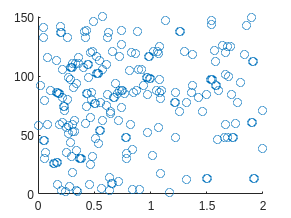

dd = spike_times(spike_times.spike_cell==48,:);

scatter(dd.spike_time, dd.spike_trial)

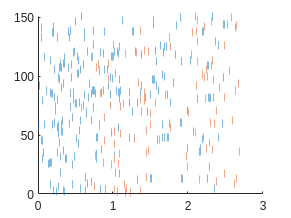

dd = spike_times(spike_times.spike_cell==48,:);
clf
hold on
scatter(dd.spike_time, dd.spike_trial,'|')
scatter(dd.response_time, dd.spike_trial,'|')
hold off

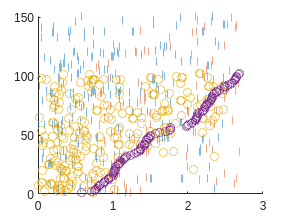

spike_cell_48 = spike_times(spike_times.spike_cell==48,:);
spike_cell_48_sorted= sortrows(spike_cell_48, "response_time");

[unique_values, ~, indices] =unique(spike_cell_48_sorted.response_time);
trial_id_sorted = indices;
spike_cell_48_sorted.trial_sorted = trial_id_sorted;


hold on
scatter(spike_cell_48_sorted.spike_time, spike_cell_48_sorted.trial_sorted)
scatter(spike_cell_48_sorted.response_time, spike_cell_48_sorted.trial_sorted)
hold off

Make an equivalent rasterplot but for cell number 187

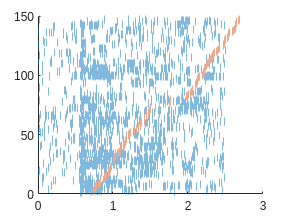

data = 1×6 cell array
    {'apple'}    {'apple'}    {'banana'}    {'banana'}    {'orange'}    {'orange'}


Original Data:


    {'apple' }
    {'apple' }
    {'banana'}
    {'banana'}
    {'orange'}
    {'orange'}



Factorized Data:


     1     1     2     2     3     3



Unique Values:


    {'apple' }
    {'banana'}
    {'orange'}



dd = spike_times(spike_times.spike_cell==187,:);
dd = sortrows(dd, "response_time");
[unique_values, ~, trial_id_sorted] =unique(dd.response_time);
dd.trial_sorted = trial_id_sorted;

clf
hold on
scatter(dd.spike_time, dd.trial_sorted, '|')
scatter(dd.response_time, dd.trial_sorted,'|')
hold off

## Spiking activity in different brain areas

ff = netcdf.NetCDF("data/steinmetz_2017-01-08_Muller.nc");

brain_region_table = ff.read2table("brain_area")

brain_region_table = 1268×2 table
    cell    brain_area
    ____    __________

      1      "PO"     
      2      "PO"     
      3      "PO"     
      4      "VISam"  
      5      "PO"     
      6      "LP"     
      7      "VISam"  
      8      "LP"     
      9      "PO"     
     10      "VISam"  
     11      "DG"     
     12      "DG"     
     13      "LP"     
     14      "PO"     
     15      "PO"     
     16      "VISam"  


ans = 50

spike_region_table = join(spike_time_table, brain_region_table, "LeftKeys","spike_cell","RightKeys","cell")

spike_region_table = 1836009×9 table
    spike_id    spike_time    spike_cell    spike_trial     gocue     response_time    feedback_time    active_trials    brain_area
    ________    __________    __________    ___________    _______    _____________    _____________    _____________    __________

        1         2.3629          1              1         0.98282        1.2333           1.2716             1             "PO"   
        2         2.3849          1              1         0.98282        1.2333           1.2716             1             "PO"   
        3         1.4507          1              2         0.90201        1.0666           1.1036             1             "PO"

unique(spike_region_table.brain_area)

ans = 6×1 string array
    "CA1"
    "DG"
    "LP"
    "PO"
    "VISam"
    "root"


groupsummary(spike_region_table,"brain_area")

ans = 6×2 table
    brain_area    GroupCount
    __________    __________

     "CA1"             78540
     "DG"         1.2453e+05
     "LP"         3.0162e+05
     "PO"         4.4547e+05
     "VISam"      3.1358e+05
     "root"       5.7228e+05


dd = spike_region_table(spike_region_table.spike_trial==187,:);
dd = sortrows(dd, "brain_area");

[unique_values, ~, ordered_index] =unique(dd.spike_cell);
dd.ordered_index = ordered_index

dd = 6736×10 table
    spike_id    spike_time    spike_cell    spike_trial    gocue    response_time    feedback_time    active_trials    brain_area    ordered_index
    ________    __________    __________    ___________    _____    _____________    _____________    _____________    __________    _____________

     59345       0.07835          27            187         NaN          NaN              NaN               0            "CA1"            20      
     59346       0.42175          27            187         NaN          NaN              NaN               0            "CA1"            20      
     59347       0.55098          27            187 

area = 'CA1';
dd_area = dd(dd.brain_area ==area,:);

scatter(dd_area.spike_time, dd_area.trial_sorted)

Error using  . 
Unrecognized table variable name 'trial_sorted'.

brain_region_table = ff.read2table({"brain_area", "spike_time"})

Error using load2table
Non-overlapping Dimension in table: spike_id cell

Error in netcdf.NetCDF/read2table (line 65)
            df = load2table(obj.filename, varnames);